%CS205 Project 2 Live Script File
addpath('E:\Spring2021\CS205\FeatureSelection\CS205_FeatureSelection')


%datafile = 'CS205_large_testdata__26.txt';
datafile = 'CS205_small_testdata__46.txt';
[for_acc, back_best, back_acc, for_feats, for_best, back_feats] = FeatureSelect(datafile);

Data contains 300 data points with 10 features each.


Level 1:
--Considering adding feature 1
----Accuracy: 0.67667
--Considering adding feature 2
----Accuracy: 0.71667
--Considering adding feature 3
----Accuracy: 0.72333
--Considering adding feature 4
----Accuracy: 0.88333
--Considering adding feature 5
----Accuracy: 0.69667
--Considering adding feature 6
----Accuracy: 0.7
--Considering adding feature 7
----Accuracy: 0.68333
--Considering adding feature 8
----Accuracy: 0.69
--Considering adding feature 9
----Accuracy: 0.67333
--Considering adding feature 10
----Accuracy: 0.68
On level 1, added feature 4.
Level 2:
--Considering adding feature 1
----Accuracy: 0.80667
--Considering adding feature 2
----Accuracy: 0.82
--Considering adding feature 3
----Accuracy: 0.91667
--Considering adding feature 5
----Accuracy: 0.84333
--Considering adding feature 6
----Accuracy: 0.84333
--Considering adding feature 7
----Accuracy: 0.80333
--Considering adding feature 8
----Accuracy: 0.83
--Considering adding feature 9
----Accuracy: 0.83
--Considering add

Elapsed time is 26.015352 seconds.


Level 1:
--Considering dropping feature 1
----Accuracy: 0.72333
--Considering dropping feature 2
----Accuracy: 0.74667
--Considering dropping feature 3
----Accuracy: 0.71667
--Considering dropping feature 4
----Accuracy: 0.68333
--Considering dropping feature 5
----Accuracy: 0.69333
--Considering dropping feature 6
----Accuracy: 0.72
--Considering dropping feature 7
----Accuracy: 0.71333
--Considering dropping feature 8
----Accuracy: 0.72
--Considering dropping feature 9
----Accuracy: 0.69667
--Considering dropping feature 10
----Accuracy: 0.71667
On level 1, dropped feature 2.
Level 2:
--Considering dropping feature 1
----Accuracy: 0.73
--Considering dropping feature 3
----Accuracy: 0.72333
--Considering dropping feature 4
----Accuracy: 0.72
--Considering dropping feature 5
----Accuracy: 0.72333
--Considering dropping feature 6
----Accuracy: 0.75333
--Considering dropping feature 7
----Accuracy: 0.73667
--Considering dropping feature 8
----Accuracy: 0.74333
--Considering dropping feat

Elapsed time is 28.086826 seconds.


PlotData(for_acc,for_feats, "Feature Selection Via Forward Selection")
PlotData(back_acc,back_feats, "Feature Selection Via Backward Selection")


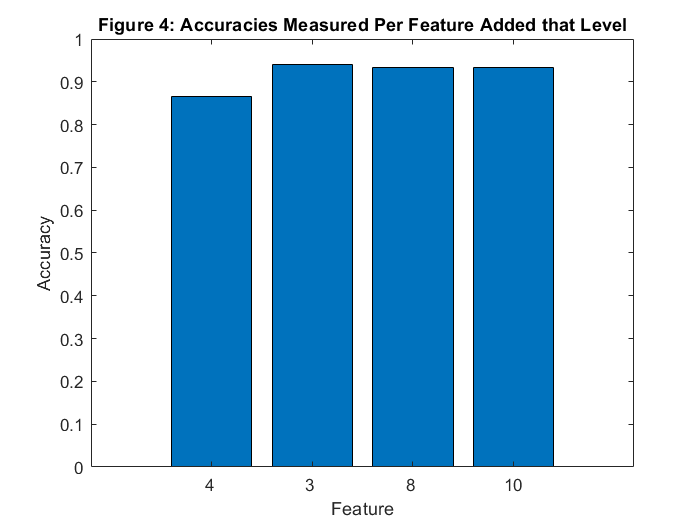

%plot data
bar(for_acc)
hold on;

set(gca,'xticklabel',ordered_features_for);
title("Figure 4: Accuracies Measured Per Feature Added that Level");
xlabel('Feature');
ylabel('Accuracy');
hold off;

%iris data found here: http://archive.ics.uci.edu/ml/datasets/Iris
irisdata = readmatrix('IrisData.txt');

disp(['Iris data contains ',num2str(size(irisdata,1)),' data points with ',num2str(size(irisdata,2)-1),' features each.']);

Iris data contains 150 data points with 4 features each.



iris_y = irisdata(:,5);
iris_x = irisdata(:,1:4);

%Forward Search
tic;
[iris_for_best , iris_for_feats, iris_for_acc]= ForwardSearch(iris_x,iris_y);

Level 1:
--Considering adding feature 1
----Accuracy: 0.58667
--Considering adding feature 2
----Accuracy: 0.46
--Considering adding feature 3
----Accuracy: 0.86667
--Considering adding feature 4
----Accuracy: 0.86667
On level 1, added feature 3.
Level 2:
--Considering adding feature 1
----Accuracy: 0.9
--Considering adding feature 2
----Accuracy: 0.90667
--Considering adding feature 4
----Accuracy: 0.94
On level 2, added feature 4.
Level 3:
--Considering adding feature 1
----Accuracy: 0.92667
--Considering adding feature 2
----Accuracy: 0.93333
On level 3, added feature 2.
Level 4:
--Considering adding feature 1
----Accuracy: 0.93333
On level 4, added feature 1.


toc;

Elapsed time is 0.956966 seconds.



for_best

for_best =      3     4


for_feats

for_feats =      3     4     2     1


for_acc

for_acc =     0.8667    0.9400    0.9333    0.9333



%Backward Search
tic;
[iris_back_best , iris_back_feats, iris_back_acc]= BackwardSearch(iris_x,iris_y);

Level 1:
--Considering dropping feature 1
----Accuracy: 0.93333
--Considering dropping feature 2
----Accuracy: 0.92667
--Considering dropping feature 3
----Accuracy: 0.92
--Considering dropping feature 4
----Accuracy: 0.92
On level 1, dropped feature 1.
Level 2:
--Considering dropping feature 2
----Accuracy: 0.94
--Considering dropping feature 3
----Accuracy: 0.90667
--Considering dropping feature 4
----Accuracy: 0.90667
On level 2, dropped feature 2.
Level 3:
--Considering dropping feature 3
----Accuracy: 0.86667
--Considering dropping feature 4
----Accuracy: 0.86667
On level 3, dropped feature 3.
Level 4:
--Considering dropping feature 4
----Accuracy: 0.32667
On level 4, dropped feature 4.


toc;

Elapsed time is 1.116993 seconds.



back_best

back_best =      3     4


back_feats

back_feats =      1     2     3     4


back_acc

back_acc =     0.9333    0.9400    0.8667    0.3267


function [best_features, ranked_features, performances] = BackwardSearch(data,class)
    best_feat_accs = [];
    cur_feats = 1:size(data,2);
    dropped_feats = [];
    for i = 1:size(data,2)
        disp(['Level ',num2str(i),':']);
        test_feat = [];
        best_acc = 0;
        
        for k = 1:size(data,2)
            if isempty(intersect(dropped_feats,k))
                disp(['--Considering dropping feature ', num2str(k)]);
                accuracy = NNValidation(data,class,setdiff(cur_feats,[dropped_feats,k]));
                disp(['----Accuracy: ',num2str(accuracy)]);
                
                if accuracy > best_acc
                    best_acc = accuracy;
                    test_feat = k;
                end
            end
        end
        dropped_feats(i) = test_feat;
        best_feat_accs(i) = best_acc;
        [~,ind] = find(cur_feats == test_feat);
        cur_feats(ind) = [];
        disp(['On level ', num2str(i),', dropped feature ',num2str(test_feat),'.']);

    end
    [~,ind] = max(best_feat_accs);
    ranked_features = dropped_feats;
    performances = best_feat_accs;
    best_features = dropped_feats;
    best_features(1:ind) = [];
end

function [best_features, ranked_features, performances] = ForwardSearch(data,class)
    best_feat_accs = [];
    cur_feats = [];
    for i = 1:size(data,2)
        disp(['Level ',num2str(i),':']);
        test_feat = [];
        best_acc = 0;
        
        for k = 1:size(data,2)
            if isempty(intersect(cur_feats,k))
                disp(['--Considering adding feature ', num2str(k)]);
                accuracy = NNValidation(data,class,[cur_feats,k]);
                disp(['----Accuracy: ',num2str(accuracy)]);
                
                if accuracy > best_acc
                    best_acc = accuracy;
                    test_feat = k;
                end
            end
        end
        cur_feats(i) = test_feat;
        best_feat_accs(i) = best_acc;
        disp(['On level ', num2str(i),', added feature ',num2str(test_feat),'.']);

    end
    [~,ind] = max(best_feat_accs);
    best_features = cur_feats(1:ind);
    ranked_features = cur_feats;
    performances = best_feat_accs;
end

%Performs data separatation and calls NN to find the total accuracies of
%of given set of features
function accuracy = NNValidation(x,y,feats)
    %edit to change cross validation group size    
    sz = size(x,1);
    
    acc = 0;
    for i = 1:sz
        itt = (i-1) + 1;
        itt2 = i;
        ts_x = x(itt:itt2,:);
        tr_x = x(1:itt-1,:);x(itt2+1:size(x,1),:);
        ts_y = y(itt:itt2);
        tr_y = y(1:itt-1,:);x(itt2+1:size(x,1));
        acc = acc + NN(tr_x,ts_x,tr_y,ts_y,feats);
    end
    accuracy = acc/sz;
end

%performs 1-Nearest Neighbor on given test set, comparing it to
function accuracy = NN(tr_x,ts_x,tr_y, ts_y, feats) %k in this case is the amount of neighbors to consider
    sum_accuracy = 0;
    for i = 1:size(ts_x,1) %for each point in the test set
        nn_y = 0;
        nn_dist = intmax;
        for y = 1:size(tr_x,1) %compare it to the points in the train set
            dist = sqrt(sum((ts_x(i,feats) - tr_x(y,feats)).^2)); %euclidean distance 
            if dist < nn_dist %and find the nearest point, record class and distance
                nn_y = tr_y(y);
                nn_dist = dist;
            end
        end
        if nn_y == ts_y(i) %if the nearest point classifies it right, it is accurate
            sum_accuracy = sum_accuracy +1;
        end
    end
    accuracy = sum_accuracy/size(ts_x,1);
end

function [for_acc, back_best, back_acc, for_feats, for_best, back_feats] = FeatureSelect(datafile)
    
    data = readmatrix(datafile);
    
    data_x = data(:,2:size(data,2));
    data_y = data(:,1);
    
    disp(['Data contains ',num2str(size(data,1)),' data points with ',num2str(size(data,2)-1),' features each.']);
    
    %Forward Search
    tic;
    [for_best , for_feats, for_acc]= ForwardSearch(data_x,data_y);
    toc;
    
    %Backward Search
    tic;
    [back_best , back_feats, back_acc]= BackwardSearch(data_x,data_y);
    toc;
    
end

function PlotData(acc, features,title)
    bar(acc)
    hold on;
    
    set(gca,'xticklabel',features);
    title(title);
    xlabel('Feature');
    ylabel('Accuracy');
    hold off;
end